% Interface trabalho 3
% Maquina de resoluçao de PVI, utilizando métodos numéricos
%INPUT:
%   strF - função da EDO y'=f(t,y)
%   [a,b] - intervalo de valores da variável independente t
%   n - número de subintervalos ou iterações do método
%   y0 - aproximação inicial y(a)=y0
%OUTPUT:
%   t - vetor do intervalo [a,b] discretizado 
%   y - vetor das soluções aproximadas do PVI em cada um dos t(i)
%
%   Alunos: Manuel Furtado a2023154006
%           Tiago Filipe a2019112767
% 
%   05/03/2024  Arménio Correia  armenioc@isec.pt

clear
format short
syms y(t)
% Dados

% help function_handle
strF = "y+exp(3*t)";

f = @(t,y) eval(vectorize(strF)); % vectorize coloca . antes de todas as *
try
    fTeste=f(t,y);
catch 
    disp(upper("Introduza uma funçao em t e y"));
end

a = 1;
b = 1.5;


if (isscalar(b) && b<a);
    disp("Introduza um b>a");
end


n = 2;
y0 = 2;


% passo 
h= (b-a)/n;

% solução exata do problema

sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
% gráfico da solução exata no intervalo [a,b]
% fplot(sExata,[a,b])

% solução exata do problema (expressão numérica)
g = @(t) eval(vectorize(char(sExata)));

% resultados e tabela de resultados

%Euler
[t,Euler] = NEuler(f,a,b,n,y0);
yExata = g(t);
erroEuler = abs(yExata-Euler);
%Euler melhorado
[~,EulerM] = Euler_Melhorado(f,a,b,n,y0);
erroEulerM = abs(yExata-EulerM);
%NRK2
[~,N2] = NRK2(f,a,b,n,y0);
erroN2 = abs(yExata-N2);
%NRK4
[~,N4] = NRK4(f,a,b,n,y0);
erroN4 = abs(yExata-N4);
%ODE45
[~,F45] = F_ODE45(f,a,b,n,y0);
erroF45 = abs(yExata-F45);
%Adams_Bashworth
[~,AB] = Adams_Bashworth(f,a,b,y0,n);
erroAB = abs(yExata-AB);


% representacao gráfica
            A = [t.',yExata.',Euler.',erroEuler.',EulerM.',erroEulerM.',N2.',erroN2.',N4.',erroN4.',F45.',erroF45.',AB.',erroAB.'];       
                tabelaResultados = array2table(A,"VariableNames", ... 
                  ["t","Exata","Euler","erroEuler","Euler M","erroEuler M","RK2","erroRK2","RK4","erroRK4","ODE 45","erroODE 45", "Adams", "erroAdams"]);
disp(tabelaResultados);

     t      Exata     Euler     erroEuler    Euler M    erroEuler M     RK2      erroRK2      RK4       erroRK4      ODE 45    erroODE 45    Adams     erroAdams
    ____    ______    ______    _________    _______    ___________    ______    ________    ______    __________    ______    __________    ______    _________

       1         2         2          0           2             0           2           0         2             0         2             0         2           0 
    1.25    10.933    7.5214      3.412 

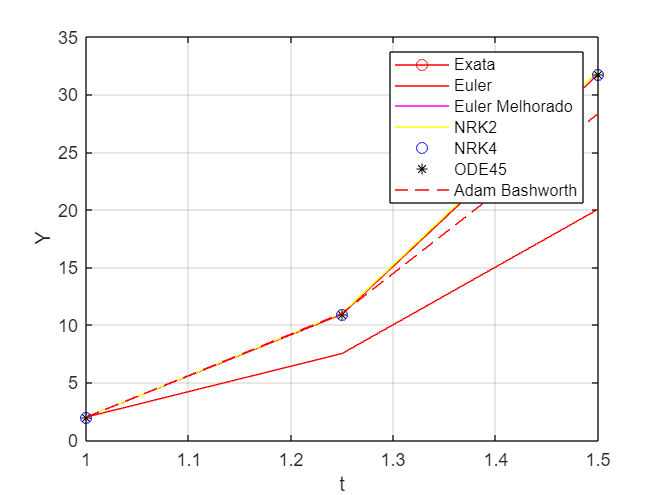


plot(t,yExata,"-ro")
hold on
plot(t,Euler,"r")
plot(t,EulerM,"m")
plot(t,N2,"y")
plot(t,N4,"bo")
plot(t,F45,"k*")
plot(t,AB,"r--")
hold off
grid on
legend('Exata','Euler','Euler Melhorado','NRK2','NRK4','ODE45','Adam Bashworth')
xlabel("t")
ylabel("Y")